% n=2;
% q = sym('q', [n, 1]);
% for i=1:n
%     nomeVariabile = ['q' num2str(i)];
%     assignin('base', nomeVariabile,q(i,1));
% end
% qd = sym('qd', [n, 1]);
% for i=1:n
%     nomeVariabile = ['qd' num2str(i)];
%     assignin('base', nomeVariabile,qd(i,1));
% end
% 
% syms a1 a2 a3 a4 real;
% a=[a1; a2; a3];

Definiamo la matrice di Inerzia

%M=[a1+2*a2*q2+a3*q2^2+2*a4*q2*sin(q3)+a5*sin(q3)^2 0 0 ; 0 a3 a4*cos(q3); 0 a4*cos(q3) a6];
%M=[a1 -a3*sin(q2);-a3*sin(q2) a2]
%c

Aggiungi altri termini del modello se presenti:

%questo lo devi sempre inizializzare
a=[A;B;CC];
%a=[a1;a2;a3;a4];
M

$$M = \left(\begin{array}{cc} A & B\,\cos\left(q_{2}\right)\\ B\,\cos\left(q_{2}\right) & \mathrm{CC} \end{array}\right)$$

c

$$c = \left(\begin{array}{c} -B\,{{\mathrm{qd}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

%gravity_terms_parametrized
thereis_c=true; 
thereis_g=false;
there_is_viscous_friction=false;


if there_is_viscous_friction
    f = sym('f', [n, 1]);
    for i=1:n
        nomeVariabile = ['f' num2str(i)];
        assignin('base', nomeVariabile,f(i,1));
    end
    a=[a;f];
    syms F;
    
    for i=1:n
        for j=1:n
            if(i==j)
                F(i,i)=f(i,1);
            end
        end
    end
end

Noi dobbiamo trovare il regressor presente nell' espressione:

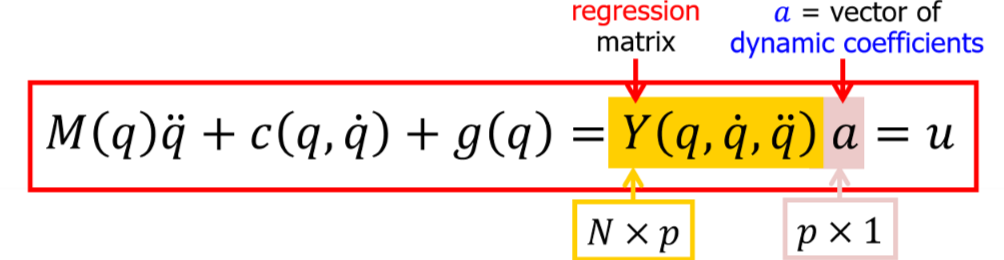

Quindi calcoliamo il modello nella forma che ci serve

qdd=sym('dqq',[n,1]);

Model_exp=M*qdd;
if(thereis_c)
    Model_exp=Model_exp+c;
end
if thereis_g
    Model_exp=Model_exp+gravity_terms_parametrized;
end
if there_is_viscous_friction
    Model_exp=Model_exp+F*qd;
end
Model_exp

$$Model\_exp = \left(\begin{array}{c} -B\,\sin\left(q_{2}\right)\,{{\mathrm{qd}}_{2}}^{2}+A\,{\mathrm{dqq}}_{1}+B\,{\mathrm{dqq}}_{2}\,\cos\left(q_{2}\right)\\ \mathrm{CC}\,{\mathrm{dqq}}_{2}+B\,{\mathrm{dqq}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$

Nota che ha dimensione nx1.

Adesso estraiamo i coefficienti che moltiplicano i dynamic coefficients e costruiamo il regressor:

Y=sym('Y',[n,size(a)]);
for i=1:n
    for j=1:size(a) 
        [coeff_of_dyn_coeff,dyn_coeff]=coeffs(Model_exp(i,1),a(j,1));
        if(dyn_coeff(1,1)==a(j,1))
            Y(i,j)=coeff_of_dyn_coeff(1,1);
        else
            Y(i,j)=0;
        end
    end
end
simplify(Y) %deve avere dimensione n x num_para

$$ans = \left(\begin{array}{ccc} {\mathrm{dqq}}_{1} & {\mathrm{dqq}}_{2}\,\cos\left(q_{2}\right)-{{\mathrm{qd}}_{2}}^{2}\,\sin\left(q_{2}\right) & 0\\ 0 & {\mathrm{dqq}}_{1}\,\cos\left(q_{2}\right) & {\mathrm{dqq}}_{2} \end{array}\right)$$

a

$$a = \left(\begin{array}{c} A\\ B\\ \mathrm{CC} \end{array}\right)$$

Il vecchio codice Buggato sicuro (questo non è stato testato abbastanza) lo trovi sulla sezione della parte 1